# **RS-WISP-08-09: Safety Ellipse in GlideSlope Approach**

**WorkerInSpace**

**Hongseok Kim**

**2025/07/13**

## III. Phase 3: Walking Safety Ellipse Approach

### III.1 Generate WSE for single $r_{\textrm{LVLH}} ,v_{\textrm{LVLH}} ,n_{\textrm{target}}$

## V. Matlab Function Test

clear; clc;
%% Input Parameters

% Target Information
Target.a = 300+6378;
Target.e = 1e-5;
Target.i = 40;
Target.RAAN = 20;
Target.AOP = 0;
Target.TA = 60;


% Chaser Information
Chaser.a = 6378 + (318.5 + 515.51)/2;
Chaser.e = (6378+515.51)/Chaser.a-1;
Chaser.i = 40.130;
Chaser.RAAN = 19.819;
Chaser.AOP = 70.662;
Chaser.TA = 349.65;


%% Main Algorithm

% Change to ECI frame

% rv data of the target wrt ECI
[r_target, v_target] = kepler2ijk_hs(Target.a, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA);

% rc data of the chaser wrt ECI
[r_chaser, v_chaser] = kepler2ijk_hs(Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA);


rho_vec_T = [0;0;0];
rho_dot_0 = -0.02;
rho_dot_T = -0.002;
N = 5;

 [T, time_vector, Delta_t, Delta_v_m_LVLH_mat, Delta_r_m_LVLH_mat ,delta_r_t_mat, delta_v_t_mat, rho_t_mat, rho_dot_t_mat, delta_v_m_plus_mat] = glideslope_transfer(r_target, v_target, r_chaser, v_chaser, rho_vec_T, rho_dot_0, rho_dot_T, N)

T = 4.4514e+03

time_vector = 1.0e+03 *

         0
    0.0090
    0.0180
    0.0270
    0.0360
    0.0450
    0.0540
    0.0629
    0.0719
    0.0809


Delta_t = 890.2747

Delta_v_m_LVLH_mat =    -0.0032   -0.0440    0.0070
   -0.0199   -0.0097    0.0195
   -0.0103   -0.0061    0.0112
   -0.0042   -0.0039    0.0060
   -0.0003   -0.0024    0.0027


Delta_r_m_LVLH_mat =    11.8169   11.9681   11.7714
    6.6346    6.7195    6.6091
    3.3648    3.4079    3.3519
    1.3017    1.3184    1.2967
    0.0000    0.0000    0.0000


delta_r_t_mat =    20.0303   20.2865   19.9531
   19.8224   20.0726   19.9702
   19.6166   19.8630   19.9851
   19.4128   19.6576   19.9979
   19.2111   19.4565   20.0085
   19.0115   19.2595   20.0170
   18.8140   19.0666   20.0233
   18.6186   18.8779   20.0274
   18.4254   18.6932   20.0293
   18.2344   18.5125   20.0291


delta_v_t_mat =    -0.0232   -0.0240    0.0020
   -0.0230   -0.0235    0.0018
   -0.0228   -0.0231    0.0015
   -0.0225   -0.0226    0.0013
   -0.0223   -0.0221    0.0011
   -0.0221   -0.0217    0.0008
   -0.0218   -0.0212    0.0006
   -0.0216   -0.0208    0.0003
   -0.0214   -0.0203    0.0001
   -0.0211   -0.0199   -0.0001


rho_t_mat =    20.0303   20.2865   19.9531
   19.5187   19.7683   19.4434
   19.0188   19.2620   18.9454
   18.5303   18.7674   18.4589
   18.0532   18.2841   17.9835
   17.5870   17.8119   17.5191
   17.1315   17.3506   17.0654
   16.6864   16.8999   16.6221
   16.2517   16.4595   16.1890
   15.8269   16.0293   15.7658


rho_dot_t_mat =    -0.0115   -0.0117   -0.0115
   -0.0112   -0.0114   -0.0112
   -0.0110   -0.0111   -0.0109
   -0.0107   -0.0109   -0.0107
   -0.0105   -0.0106   -0.0104
   -0.0102   -0.0104   -0.0102
   -0.0100   -0.0101   -0.0100
   -0.0098   -0.0099   -0.0097
   -0.0096   -0.0097   -0.0095
   -0.0093   -0.0095   -0.0093


delta_v_m_plus_mat =    -0.0232   -0.0240    0.0020
   -0.0135   -0.0148    0.0007
   -0.0074   -0.0089   -0.0001
   -0.0035   -0.0052   -0.0006
   -0.0010   -0.0029   -0.0009


 total_elapsed_time = T/3600

total_elapsed_time = 1.2365

### III.2 Generate WSE for Each Maneuver

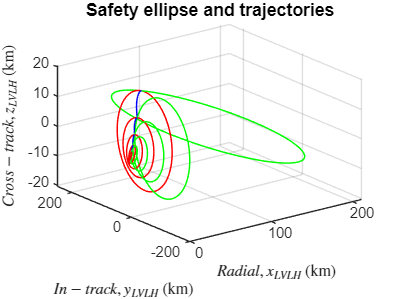


    figure;
    hold on
    grid on
    
    
    r_lvlh_datapoint = [delta_r_t_mat(1,:);
                        Delta_r_m_LVLH_mat];


    v_lvlh_plus_datapoint = [delta_v_m_plus_mat;
                        delta_v_t_mat(end,:)];

    v_lvlh_minus_datapoint = [delta_v_m_plus_mat-Delta_v_m_LVLH_mat];

    number_of_ellipse = length(r_lvlh_datapoint(:,1));
    mu = 398600.4415;

    r_target_eci = r_target;
    n_target_vehicle = sqrt(mu/norm(r_target_eci)^3);


    x_max_plus_data = [];
    z_max_plus_data = [];
    x_c_plus_data = [];
    y_c_plus_data = [];
    y_dot_c_plus_data = [];

    x_max_minus_data = [];
    z_max_minus_data = [];
    x_c_minus_data = [];
    y_c_minus_data = [];
    y_dot_c_minus_data = [];


    for ellipse_index = 1:number_of_ellipse
    r_lvlh = r_lvlh_datapoint(ellipse_index,:)';
    v_lvlh = v_lvlh_plus_datapoint(ellipse_index,:)';

    x_0 = r_lvlh(1); y_0 = r_lvlh(2); z_0 = r_lvlh(3);
    x_dot_0 = v_lvlh(1); y_dot_0 = v_lvlh(2); z_dot_0 = v_lvlh(3);
    n = n_target_vehicle;

    [x_max, y_max, z_max, x_c, y_c, y_dot_c, alpha, beta] = get_safety_ellipse_params(x_0, y_0, z_0, x_dot_0, y_dot_0, z_dot_0, n);
    x_max_plus_data = [x_max_plus_data;x_max];
    z_max_plus_data = [z_max_plus_data;z_max];
    x_c_plus_data = [x_c_plus_data;x_c];
    y_c_plus_data = [y_c_plus_data;y_c];
    y_dot_c_plus_data = [y_dot_c_plus_data;y_dot_c];

       %nt = linspace(0,2*pi*number_of_periods);
       nt = 0:0.1:2.1*pi;
       x_t = x_max * cos(nt + alpha) + x_c;
       y_t = -2 * x_max * sin(nt+alpha) + y_c;
       z_t = z_max * cos(nt + beta);
       chaser_trajectory_data = [x_t', y_t', z_t'];
       % scatter3(x_c,y_c,0,'filled') % Center of Ellipse
       % scatter3(x_0, y_0, z_0,'filled') % Chaser Location
       % scatter3(0,0,0,'filled') % Target Location
       plot3(x_t,y_t,z_t,'red','LineWidth',1)
       % q2 = quiver3(x_c,y_c,0,0,y_dot_c*2*pi/n,0,'g','LineWidth',3); % SE Moving Direction

   end


    for ellipse_index = 1:number_of_ellipse-1
    r_lvlh = r_lvlh_datapoint(ellipse_index,:)';
    v_lvlh = v_lvlh_minus_datapoint(ellipse_index,:)';

    x_0 = r_lvlh(1); y_0 = r_lvlh(2); z_0 = r_lvlh(3);
    x_dot_0 = v_lvlh(1); y_dot_0 = v_lvlh(2); z_dot_0 = v_lvlh(3);
    n = n_target_vehicle;

    [x_max, y_max, z_max, x_c, y_c, y_dot_c, alpha, beta] = get_safety_ellipse_params(x_0, y_0, z_0, x_dot_0, y_dot_0, z_dot_0, n);
    x_max_minus_data = [x_max_minus_data;x_max];
    z_max_minus_data = [z_max_minus_data;z_max];
    x_c_minus_data = [x_c_minus_data;x_c];
    y_c_minus_data = [y_c_minus_data;y_c];
    y_dot_c_minus_data = [y_dot_c_minus_data;y_dot_c];

       %nt = linspace(0,2*pi*number_of_periods);
       nt = 0:0.1:2.1*pi;
       x_t = x_max * cos(nt + alpha) + x_c;
       y_t = -2 * x_max * sin(nt+alpha) + y_c;
       z_t = z_max * cos(nt + beta);
       chaser_trajectory_data = [x_t', y_t', z_t'];
       % scatter3(x_c,y_c,0,'filled') % Center of Ellipse
       % scatter3(x_0, y_0, z_0,'filled') % Chaser Location
       % scatter3(0,0,0,'filled') % Target Location
       plot3(x_t,y_t,z_t,'green','LineWidth',1)
       % q2 = quiver3(x_c,y_c,0,0,y_dot_c*2*pi/n,0,'g','LineWidth',3); % SE Moving Direction

   end


   plot3(delta_r_t_mat(:,1), delta_r_t_mat(:,2), delta_r_t_mat(:,3),'blue','LineWidth',1)
   view(3)
   xlabel( '$Radial, x_{LVLH}$ (km)', 'Interpreter', 'latex')
   ylabel('$In-track, y_{LVLH}$ (km)', 'Interpreter', 'latex')
   zlabel('$Cross-track, z_{LVLH}$ (km)', 'Interpreter', 'latex')
   title('Safety ellipse and trajectories','FontSize',12,'FontWeight','bold')

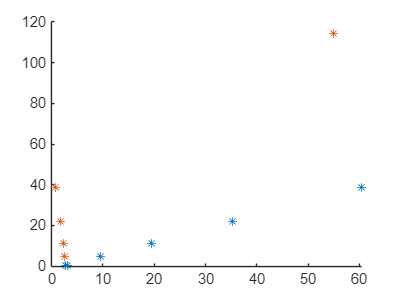

   % legend('Starting Center of Ellipse', 'Chaser Starting location', 'Target Location','Chaser Trajectory','SE Moving Direction','SE Visualization')


 safety_ellipse_plus_data = [x_max_plus_data, z_max_plus_data, x_c_plus_data, y_c_plus_data, y_dot_c_plus_data];
 safety_ellipse_minus_data = [x_max_minus_data, z_max_minus_data, x_c_minus_data, y_c_minus_data, y_dot_c_minus_data];

 figure
 hold on
 scatter(y_c_plus_data, x_c_plus_data,'*')
 scatter(y_c_minus_data, x_c_minus_data,'*')
 hold off

## III.3 Function for get safety ellipse parmeters

function [x_max, y_max, z_max, x_c, y_c, y_dot_c, alpha, beta] = get_safety_ellipse_params(x_0, y_0, z_0, x_dot_0, y_dot_0, z_dot_0, n)


  x_c = 4*x_0 + 2*y_dot_0/n;
  y_c = -2*x_dot_0/n+y_0;
  y_dot_c = -3*n/2*x_c;
  
  x_max = sqrt((x_dot_0/n)^2+(3*x_0 +2*y_dot_0/n)^2);
  y_max = 2 * x_max;
  z_max = sqrt((z_dot_0/n)^2+z_0^2);

  cos_alpha = -1/x_max * (3*x_0 +2*y_dot_0/n);
  sin_alpha = -1/x_max * (x_dot_0/n);

  if sin_alpha >= 0
    alpha = acos(cos_alpha);
  else
    alpha = 2*pi - acos(cos_alpha);
  end



  cos_beta = z_0/z_max;
  sin_beta = -1/z_max * z_dot_0/n;

  if sin_beta>=0
      beta = acos(cos_beta);
  else
      beta = 2*pi - acos(cos_beta);
  end

  if isnan(beta) == true
   beta = 0;
  end
end

## Appendix 1: 2-body orbit propagator in ECI

function dydt = two_body_dynamics(t,y)

 % Define the standard gravitational parameter for Earth (km^3/s^2)
    mu = 398600.4415;
 
 % Extract position and velocity from the input state vector
    r_vec = y(1:3); % Position vector
    v_vec = y(4:6); % Velocity vector

 % Calculate the norm of the position vector
    r_norm = norm(r_vec);

 % Compute the acceleration based on the gravitational force
   a1 = -mu*r_vec(1)/(r_norm^3);
   a2 = -mu*r_vec(2)/(r_norm^3);
   a3 = -mu*r_vec(3)/(r_norm^3);

 % Combine velocity and acceleration to form the derivative of the state vector
    dydt = [v_vec; a1;a2;a3];
end



function [t,y] = orbit_propagation(r0, v0, tVec)

    odeoptions = odeset('RelTol',1e-10,'AbsTo',1e-20);
    % Calculate the magnitude of the position and velocity vectors
    y0 = [r0;v0];
    
    % Solve the ODE using ode45
    [t, y] = ode45(@two_body_dynamics, tVec, y0, odeoptions);
end

## Appendix 2: ECI to Keplerian Converter (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;
end



## Algorithm 3.4 Coordinate Transform between ECI and LVLH

function [r_lvlh, v_lvlh] = eci2lvlh(r_t_eci, v_t_eci, r_c_eci, v_c_eci, n)

  i_hat = r_t_eci/norm(r_t_eci);
  k_hat = cross(r_t_eci, v_t_eci)/norm(cross(r_t_eci, v_t_eci));
  j_hat = cross(k_hat,i_hat)/norm(cross(k_hat,i_hat));

  Q_lvlh_eci = [i_hat'; j_hat'; k_hat'];

  r_lvlh = Q_lvlh_eci * (r_c_eci - r_t_eci);
  v_lvlh = Q_lvlh_eci * (v_c_eci - v_t_eci - n*cross(k_hat,r_c_eci - r_t_eci));

end




function [r_c_eci, v_c_eci] = lvlh2eci(r_t_eci, v_t_eci, r_lvlh, v_lvlh)

  i_hat = r_t_eci/norm(r_t_eci);
  k_hat = cross(r_t_eci, v_t_eci)/norm(cross(r_t_eci, v_t_eci));
  j_hat = cross(k_hat,i_hat)/norm(cross(k_hat,i_hat));

  Q_eci_lvlh = [i_hat, j_hat, k_hat];

  r_c_eci = Q_eci_lvlh * r_lvlh + r_t_eci;
  v_c_eci = Q_eci_lvlh * v_lvlh + v_t_eci + n* cross(k_hat , r_c_eci - r_t_eci);

end

## Appeneix: Glideslope Approach Algorithm

function [T, time_vector, Delta_t, Delta_v_m_LVLH_mat, Delta_r_m_LVLH_mat ,delta_r_t_mat, delta_v_t_mat, rho_t_mat, rho_dot_t_mat, delta_v_m_plus_mat] = glideslope_transfer(r_target, v_target, r_chaser, v_chaser, rho_vec_T, rho_dot_0, rho_dot_T, N)

r_0 = r_target;
v_0 = v_target;
r = r_chaser;
v = v_chaser;

% Reference Frame of the Target
i_hat = r_0/norm(r_0);
j_hat = v_0/norm(v_0);
k_hat = cross(i_hat, j_hat);

% Transformation Matrix from ECI to Space Station Frame
Q_LVLH_ECI = [i_hat';j_hat';k_hat'];

% Position vector of the spacecraft relative to the space station (ECI)
delta_r = r - r_0;
n = norm(v_0)/norm(r_0);
Omega_target = n * k_hat;
delta_v = v - v_0 - cross(Omega_target, delta_r);

% Relative position vector at the beginning of the rendezvous maneuver
delta_r_0 = Q_LVLH_ECI * delta_r;

% Relative velocity just before launch into the rendezvous trajectory
delta_v_0_minus = Q_LVLH_ECI * delta_v;

% 6. Get rho_0_vec, rho_0, and u_rho

rho_0_vec = delta_r_0 - rho_vec_T;
rho_0 = norm(rho_0_vec);
u_rho = rho_0_vec / rho_0;

% 7. Caculate slope a, total time T, and rho_vec_t, rho_dot_t;

a = (rho_dot_0 - rho_dot_T)/rho_0;
T = 1/a * log(rho_dot_T/rho_dot_0);
Delta_t = T/N;


% 7.1 Generate dataset of rho_t and rho_dot_t
t_vec = linspace(0,T);
rho_t_mat = zeros(length(t_vec),3);
rho_dot_t_mat = zeros(length(t_vec),3);


    for time_index = 1:length(t_vec)
        t = t_vec(time_index);
        rho_t = rho_0 * exp(a*t) + (rho_dot_T/a) * (exp(a*t)-1);
        rho_vec_t = rho_t * u_rho;
        rho_dot_vec_t = (a * rho_t + rho_dot_T) * u_rho;
        rho_t_mat(time_index,:) = rho_vec_t';
        rho_dot_t_mat(time_index,:) = rho_dot_vec_t'; 
    end


% 8.1 Caculate delta_v_m_plus, delta_v_m_minus, Delta_v_m

delta_v_m_minus_mat = zeros(N+1,3);
delta_v_m_minus_mat(1,:) = delta_v_0_minus';
delta_r_m_mat = zeros(N+1,3);
delta_r_m_mat(1,:) = delta_r_0';
delta_v_m_plus_mat = zeros(N,3);
Delta_v_m_LVLH_mat = zeros(N,3);
Delta_r_m_LVLH_mat = zeros(N,3);

delta_r_t_mat = [];
delta_v_t_mat = [];
time_vector = [];

delta_t_vec = linspace(0,Delta_t);
delta_r_t_mat_temp = zeros(length(delta_t_vec),3);
delta_v_t_mat_temp = zeros(length(delta_t_vec),3);


[Phi_rr_Delta_t, Phi_rv_Delta_t, Phi_vr_Delta_t, Phi_vv_Delta_t] = cw_matrix_generator(n,Delta_t);

    for m = 1:N
    
        t_m = m * Delta_t;
        rho_m = rho_0 * exp(a * t_m) + (rho_dot_T / a) * (exp(a*t_m)-1);
        delta_r_m = delta_r_m_mat(m,:)';
        delta_r_m_plus_1 = rho_vec_T + rho_m * u_rho;
        delta_r_m_mat(m+1,:) = delta_r_m_plus_1';
        
        delta_v_m_plus = inv(Phi_rv_Delta_t) * (delta_r_m_plus_1 - Phi_rr_Delta_t * delta_r_m);
        delta_v_m_plus_1_minus = Phi_vr_Delta_t * delta_r_m + Phi_vv_Delta_t * delta_v_m_plus;
        
        delta_v_m_minus_mat(m+1,:) = delta_v_m_plus_1_minus';
        delta_v_m_plus_mat(m,:) = delta_v_m_plus;
        Delta_v_m_LVLH_mat(m,:) =  (delta_v_m_plus - delta_v_m_minus_mat(m,:)')';
        Delta_r_m_LVLH_mat(m,:) = delta_r_m_plus_1';

        for t_index = 1:length(delta_t_vec)
    
            t = delta_t_vec(t_index);
            [Phi_rr, Phi_rv, Phi_vr, Phi_vv] = cw_matrix_generator(n,t);
    
            delta_r_t = Phi_rr * delta_r_m + Phi_rv * delta_v_m_plus;
            delta_v_t = Phi_vr * delta_r_m + Phi_vv * delta_v_m_plus;
    
            delta_r_t_mat_temp(t_index,:) = delta_r_t';
            delta_v_t_mat_temp(t_index,:) = delta_v_t';
        end
    
        delta_r_t_mat = [delta_r_t_mat;delta_r_t_mat_temp];
        delta_v_t_mat = [delta_v_t_mat;delta_v_t_mat_temp];

        time_info = delta_t_vec + (m-1) * Delta_t;

        time_vector = [time_vector;time_info'];
    end

end

## Appendix 1: Clohessy-Wilshire Matrix Generator 

function [Phi_rr, Phi_rv, Phi_vr, Phi_vv] = cw_matrix_generator(n,t)

nt = n*t;

Phi_rr = [4 - 3*cos(nt),   0, 0;
          6*(sin(nt) - nt),1,0;
          0,0, cos(nt)];

Phi_rv = [sin(nt)/n, 2/n * (1 - cos(nt)), 0;
          2/n*(cos(nt)-1), 4/n*sin(nt)-3*t,0;
          0,0,1/n*sin(nt)];

Phi_vr = [3*n*sin(nt),0,0;
          6*n*(cos(nt)-1),0,0;
          0,0,-n*sin(nt)];
Phi_vv = [cos(nt), 2*sin(nt),0
         -2*sin(nt), 4*cos(nt)-3, 0;
          0,0,cos(nt)];
end